%% Nonparametric
clear

nbins = 6; % how many dispersal bins to use (2<=nbins)
ndiv = 6; % increments by which to shift when generating kernels

bars = nchoosek(1:(nbins+ndiv-1),(nbins-1)); % locations of bars in "bars and stars" proof
bars = [zeros(length(bars),1) bars (nbins+ndiv)*ones(length(bars),1)];

kernels = ones(length(bars),nbins);

for j=1:length(bars)
    for i=1:nbins
        kernels(j,i) = bars(j,i+1)-bars(j,i)-1;
    end
end

kernels = (1/ndiv)*kernels;


## Weibull

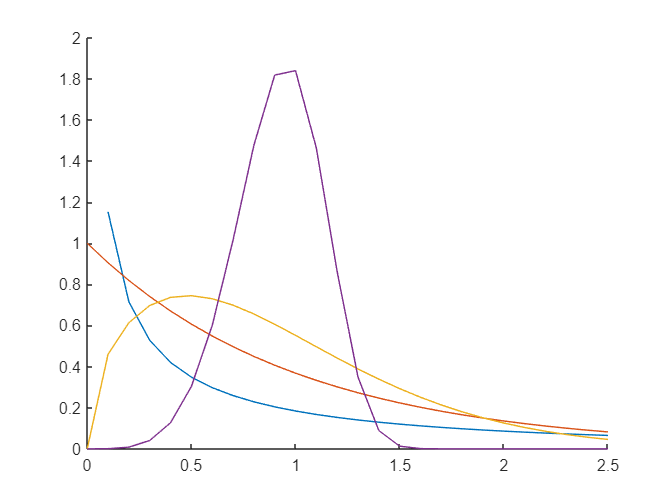

% check our function definitions produce expected results
% (they match the wikipedia plots)
seq = 0:0.1:2.5;
%pdfs:
figure
clf
hold on
plot(seq,weibull_pdf(seq,1,0.5))
plot(seq,weibull_pdf(seq,1,1))
plot(seq,weibull_pdf(seq,1,1.5))
plot(0:0.1:2.5,weibull_pdf(0:0.1:2.5,1,5))
hold off

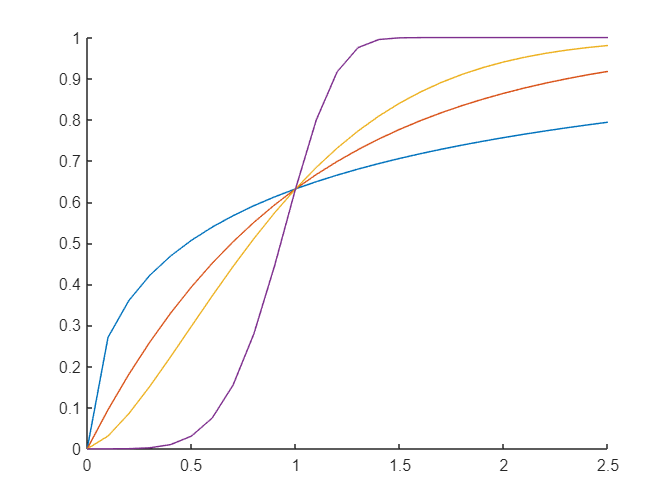

%cdfs:
figure
clf
hold on
plot(seq,weibull_cdf(seq,1,0.5))
plot(seq,weibull_cdf(seq,1,1))
plot(seq,weibull_cdf(seq,1,1.5))
plot(seq,weibull_cdf(seq,1,5))
hold off

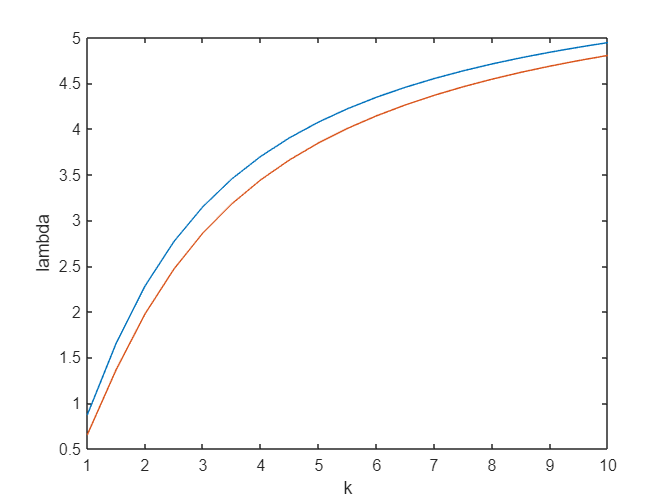

% values of lambda and k s.t. cdf at x=6 is greater than 0.999
ks = 1:0.5:10;
lambdas = 6.*((-log(0.001)).^(-1./ks));
lambdas2 = 6.*((-log(0.0001)).^(-1./ks));
plot(ks,lambdas,ks,lambdas2)
xlabel('k')
ylabel('lambda')

% so, eg., k=4, lambda=3.5 is between the two lines: cdf at 6 should be
% >0.999 but <0.9999
weibull_cdf(6,3.5,4)

ans = 0.9998

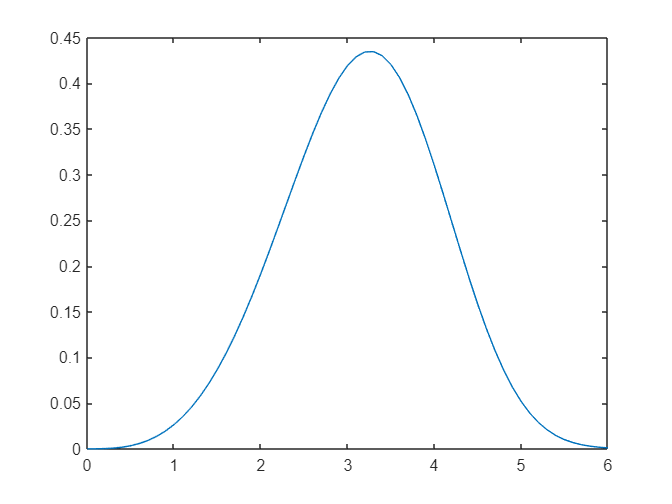

seq = 0:0.1:6;
plot(seq,weibull_pdf(seq,3.5,4))

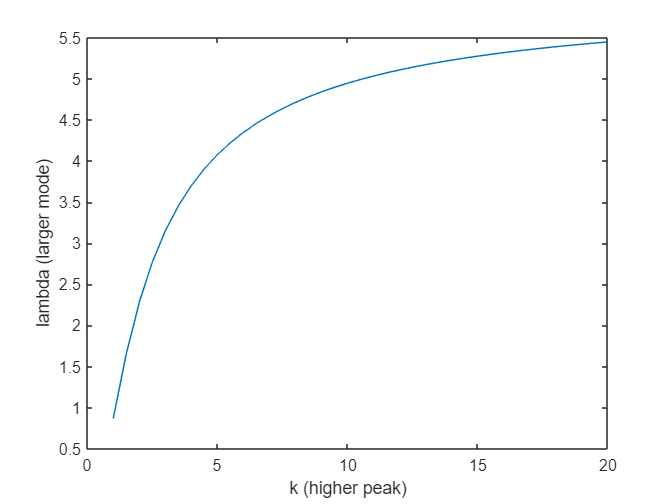

% we want a list of combinations of k and lambda values that cover the area
% below the curve
ks = 1:0.5:20;
lambdas = 6.*((-log(0.001)).^(-1./ks));
plot(ks,lambdas)
xlabel('k (higher peak)')
ylabel('lambda (larger mode)')

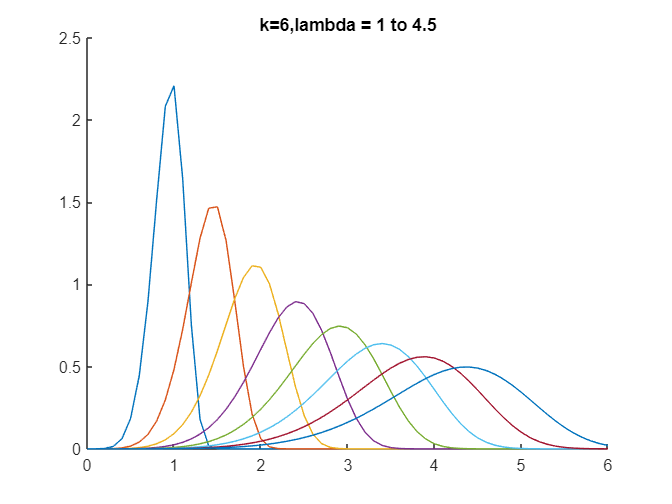

seq = 0:0.1:6;
figure
clf
hold on
plot(seq,weibull_pdf(seq,1,6))
plot(seq,weibull_pdf(seq,1.5,6))
plot(seq,weibull_pdf(seq,2,6))
plot(seq,weibull_pdf(seq,2.5,6))
plot(seq,weibull_pdf(seq,3,6))
plot(seq,weibull_pdf(seq,3.5,6))
plot(seq,weibull_pdf(seq,4,6))
plot(seq,weibull_pdf(seq,4.5,6)) %this one's out of bounds
title('k=6,lambda = 1 to 4.5')
hold off

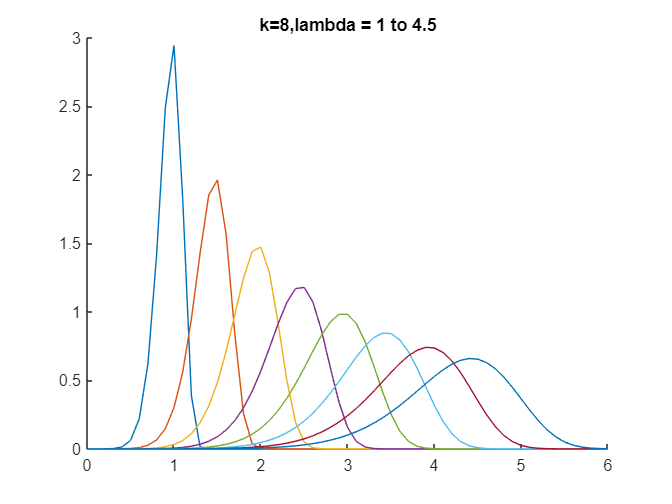


figure
clf
hold on
plot(seq,weibull_pdf(seq,1,8))
plot(seq,weibull_pdf(seq,1.5,8))
plot(seq,weibull_pdf(seq,2,8))
plot(seq,weibull_pdf(seq,2.5,8))
plot(seq,weibull_pdf(seq,3,8))
plot(seq,weibull_pdf(seq,3.5,8))
plot(seq,weibull_pdf(seq,4,8))
plot(seq,weibull_pdf(seq,4.5,8))
title('k=8,lambda = 1 to 4.5')
hold off

% k controls the height of the peak, and lambda controls its location

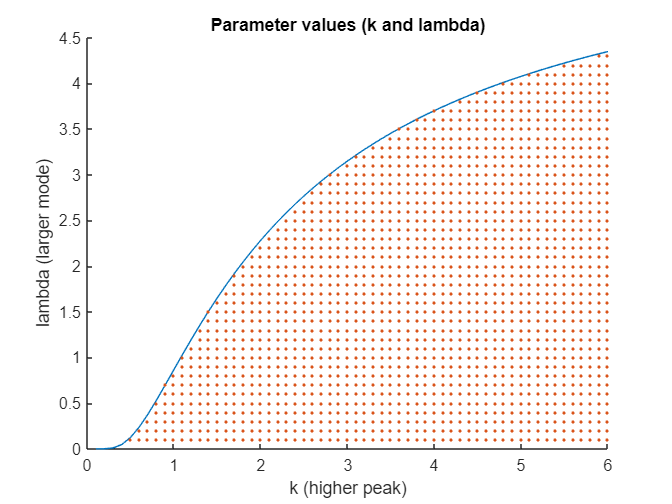

% let's try k up to 6, and the appropriate values of lambda, as our
% parameter combos
clear

params=[]; %k, lambda
for k_i = 0.1:0.1:6
    lambda_i_max = 6.*((-log(0.001)).^(-1./k_i));
    lambdas_i = 0.1:0.1:lambda_i_max;
    n_i = size(lambdas_i,2);
    new = [k_i*ones(n_i,1),lambdas_i'];
    params = [params;new];
end

save('weibull_params.mat','params');

ks = 0.1:0.1:6;
figure
clf
hold on
lambdas = 6.*((-log(0.001)).^(-1./ks));
plot(ks,lambdas,'-')
plot(params(:,1),params(:,2),'.')
xlabel('k (higher peak)')
ylabel('lambda (larger mode)')
title('Parameter values (k and lambda)')
hold off

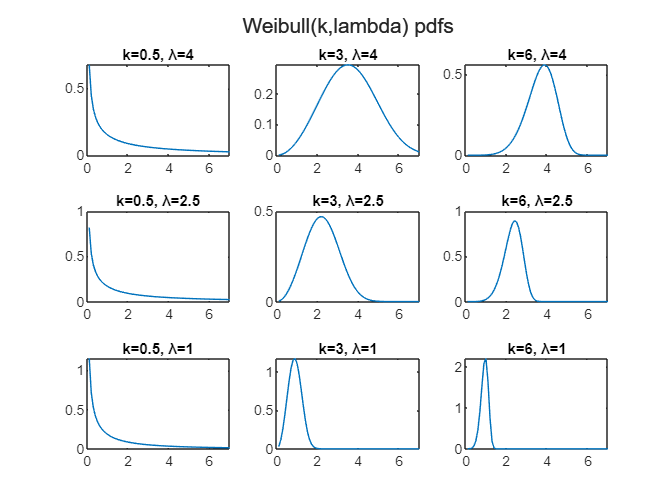

t = tiledlayout(3,3);
title(t,'Weibull(k,lambda) pdfs')
%k = 0.5,3,6
%lambda = 0.1,2.5,4

seq = 0.1:0.1:7;
lambdas = [4 2.5 1];
ks = [0.5 3 6];

for i=1:3 %row, starting on top
    for j=1:3 %column, starting on left
        nexttile
        lambda = lambdas(i);
        k = ks(j);
        plot(seq,weibull_pdf(seq,lambda,k))
        title(sprintf('k=%g, \x03bb=%g',k,lambda))
    end
end

%make it discrete
nbins = 6; % how many dispersal bins to use (2<=nbins)
cdfs = weibull_cdf(1:6,params(:,2),params(:,1));
cdfs = [zeros(size(cdfs,1),1) cdfs];
kerns = [];
for i=1:6
    kerns(:,i) = cdfs(:,i+1)-cdfs(:,i);
end

n_kern = 55;
figure
clf
hold on
bar(0:5,kerns(n_kern,:))
plot(0.1:0.1:6,weibull_pdf(0.1:0.1:6,params(n_kern,2),params(n_kern,1)))
xlim([-0.5 6])
hold off

save('weibull_kerns.mat','kerns');